# Variable eddy viscosity Ekman layer in the atmospheric boundary layer (1D)

## Introduction

In the atmospheric boundary layer, the simplified steady-state momentum equations for a horizontally homogeneous incompressible flow can be written as: 

 $K \frac{\partial^2 u}{\partial z^2}  = -f v  \\
K \frac{\partial^2 v}{\partial z^2}  = -f (u_g - u)
$         (1)

 where $z$ is the altitude above ground; $u$ is the East-West wind velocity component and $v$ the north-south velocity component. The term $K$ is here a constant and correspond to the eddy viscosity. Setting the boundaries conditions are $u(z=0) = 0$, $v(z=0) = 0$,  $u(z \rightarrow \infty) = u_g$ and  $v(z \rightarrow \infty) = 0$, the analytical solutions of these equations are:

$u(z)  = u_g \left[1-\exp\left(-\gamma z\right) \cos\left(\gamma z\right)\right]  \\ 
	v(z) = u_g \exp\left(-\gamma z\right) \sin\left(\gamma z\right)$         (2)

where $\gamma = \sqrt{\frac{f}{2K}}$ has the dimension of the inverse of a distance and  $f$ is the Coriolis parameter:

$f  = 2 \Omega \sin\left(\phi\right)$,

where $\Omega = 7.2921e-5$ rad s$^{-1}$is the rotation rate of the Earth and  $\phi
$is the latitude (in degrees).

In the atmospheric boundary layer, the  eddy viscosity $K$is not constant and equation (1) is not valid. Instead, the following equations need to be solved:

$\frac{\partial}{\partial z} \left( K(z) \frac{\partial u}{\partial z}\right)  = -f v  \\
\frac{\partial}{\partial z} \left( K(z) \frac{\partial v}{\partial z}\right)   = -f (u_g - u)
$         (3)

In the present submission, equation (3) is numerically solved using the explicit finite difference method and height-dependant eddy viscosity models from [1]. Some of the figures in ref [1] are thus reproduced. The original source of inspiration for the present submission is the Matlab script by James Price [2] that was modified to account for height-dependant viscosity models.

References:

[1] Berger, B. W., & Grisogono, B. (1998). The baroclinic, variable eddy viscosity Ekman layer. *Boundary-layer meteorology*, *87*(3), 363-380.

[2] https://www.whoi.edu/science/PO/people/jprice/website/education_scripts.html

## Definition of constants and K(z)

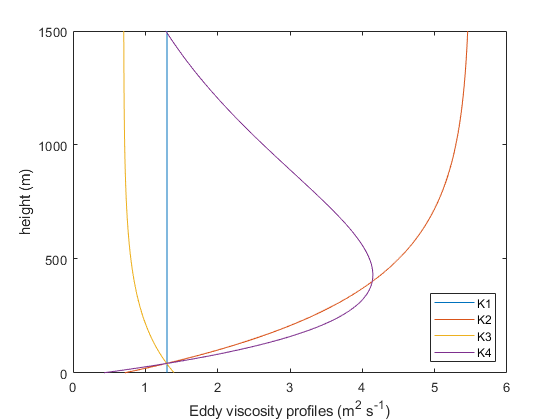

clearvars;close all;clc;
rho = 1.25; % air density
h = 1500; % maximal height modelled
Nz= 200; % Number of points in the vertical directin
Nk = 4; % number of edddy viscosity profiles studied
Ug = 9; % Geostrophic wind velocity
latitude = 40; % latitude (in degrees) - A little unsure if it corresponds to the one used by [1]

z = linspace(1,h,Nz); % height vector
dz = median(diff(z));

% anonymous function fo define K2,K3 and K4
getK_V1 = @(K0,K_hat,K_star,z_star,z)  K_hat + (K0-K_hat).*exp(z/z_star.*(log((K_star-K_hat)./(K0-K_hat))));
getK_V2 = @(a0,a1,K0,K_hat,K_star,z_star,z)  (a0 + a1.*z).*K0.*exp(z/z_star.*(log((K_star-K_hat)./(K0-K_hat))));

% derivative of K w.r.t. z
get_K1_p = @(K0,K_hat,K_star,z_star,z) (exp((z.*log(-(K_hat - K_star)./...
    (K0 - K_hat)))./z_star).*log(-(K_hat - K_star)./(K0 - K_hat))*(K0 - K_hat))./z_star;
getK_V2_p = @(a0,a1,K0,K_hat,K_star,z_star,z)  K0*a1*exp((z*log(-(K_hat - K_star)./...
    (K0 - K_hat)))./z_star) + (K0.*exp((z.*log(-(K_hat - K_star)./(K0 - K_hat)))./z_star).*...
    log(-(K_hat - K_star)./(K0 - K_hat)).*(a0 + a1*z))./z_star;


% Definitions of K1,K2, K3 and K4 following [1]
Nk = 4;
K = zeros(Nk,Nz);
Kp = zeros(Nk,Nz); % derivative of K w.r.t. z

% Case 1
K(1,:) = 1.3.*ones(1,Nz); % K1

% Case 2
K0 = 0.7; K_hat = 5.5; K_star = 4.5; z_star = 500;
K(2,:) = getK_V1(K0,K_hat,K_star,z_star,z); % K2
Kp(2,:) = get_K1_p(K0,K_hat,K_star,z_star,z);


% Case 3
K0 = 1.4; K_hat = 0.7; K_star = 0.8; z_star = 500;
K(3,:) = getK_V1(K0,K_hat,K_star,z_star,z); % K3
Kp(3,:) = get_K1_p(K0,K_hat,K_star,z_star,z);

% Case 4
a0 = 0.9; a1 = 2.7/50; K0 = 0.45; K_hat = 0.1; K_star = 0.3; z_star = 250;
K(4,:) = getK_V2(a0,a1,K0,K_hat,K_star,z_star,z); % K4
Kp(4,:) = getK_V2_p(a0,a1,K0,K_hat,K_star,z_star,z); % K4

figure
plot(K,z)
legend('K1','K2','K3','K4','location','southeast')
xlabel('Eddy viscosity profiles (m^2 s^{-1})')
ylabel('height (m)')

set(gcf,'color','w')

## Comparison with analytical solution of the Ekman quations (constant K)

[u1,v1] = EkmanAnalytic(Ug,K(1,1),latitude,z);

dt =15;
[u2,v2,u2t,v2t,t2] = solveEkman(z,Ug,K(1,1),latitude,'critConv',1e-5,'Nmax',5e5,'dt',dt,'method','Euler');

The algorithm has converged 


[u3,v3,u3t,v3t,t3] = solveEkman(z,Ug,K(1,1),latitude,'critConv',1e-5,'Nmax',5e5,'dt',dt,'method','RK4');

The algorithm has converged 


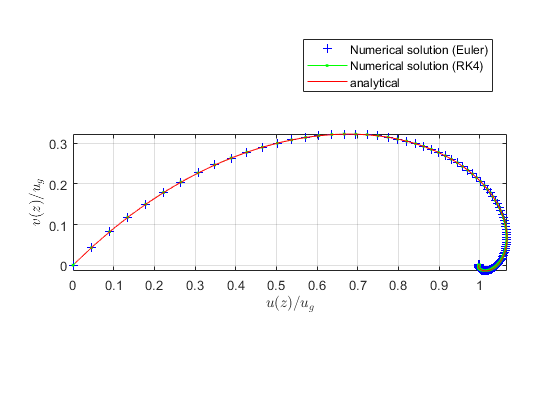

% 
% figure
% plot(t2,u2t(:,100),'k',t3,u3t(:,100),'r--');legend('Euler','Rk4')

clf;close all;
plot(u2./Ug,v2./Ug,'b+',u3./Ug,v3./Ug,'g.-');
hold on;
plot(u1./Ug,v1./Ug,'r');
legend('Numerical solution (Euler)','Numerical solution (RK4)','analytical','location','best')
axis tight
axis equal
grid on
xlabel('$u(z)/u_g$','interpreter','latex')
ylabel('$v(z)/u_g$','interpreter','latex')

set(gcf,'color','w')

## Ekman spiral with and without height-dependant K

[u1,v1] = solveEkman(z,Ug,K(1,:),latitude,'critConv',1e-5,'Nmax',5e4);

The algorithm has converged 


[u2,v2] = solveEkman(z,Ug,K(4,:),latitude,'critConv',1e-5,'Nmax',1e5);

The algorithm has converged 


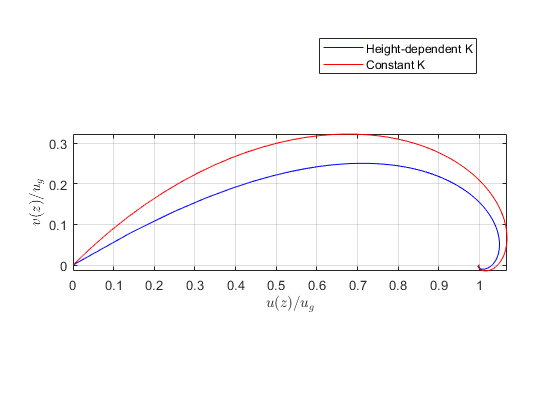

clf;close all;
figure
set(gcf,'color','w')
plot(u2./Ug,v2./Ug,'b');
hold on;
plot(u1./Ug,v1./Ug,'r');
legend('Height-dependent K','Constant K','location','best')
axis tight
axis equal
grid on
xlabel('$u(z)/u_g$','interpreter','latex')
ylabel('$v(z)/u_g$','interpreter','latex')

## Computation of the wind speed profiles

clf;close all;

u = nan(Nk,Nz);
v = nan(Nk,Nz);
tau = nan(Nk,Nz);
Theta = nan(Nk,Nz);
for ii=1:Nk
    Ki = K(ii,:);
    [u(ii,:),v(ii,:)] = solveEkman(z,Ug,Ki,latitude,'critConv',1e-5,'Nmax',1e5);
    dudz = diff([0 u(ii,:)])./dz;
    dvdz = diff([0 v(ii,:)])./dz;
    tu = rho.*Ki.*dudz;
    tv = rho.*Ki.*dvdz;
    tau(ii,:) = sqrt(tu.^2+tv.^2);
    Theta(ii,:) = 180/pi.*atan2(v(ii,:),u(ii,:));
end

The algorithm has converged 
The algorithm has converged 
The algorithm has converged 
The algorithm has converged 


Theta(:,1) = Theta(:,2); % The bottom value is assumed equal to the second lowest one
tau(:,1) = tau(:,2);% The bottom value is assumed equal to the second lowest one

## Visualization of the profiles

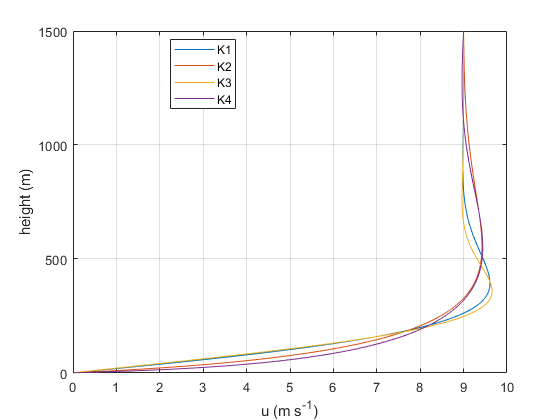

figure
for ii=1:Nk
    plot(u(ii,:),z)
    hold on; box on;
    xlabel('u (m s^{-1})')
    ylabel('height (m)')
    set(gcf,'color','w')
end
legend('K1','K2','K3','K4','location','best')
grid on

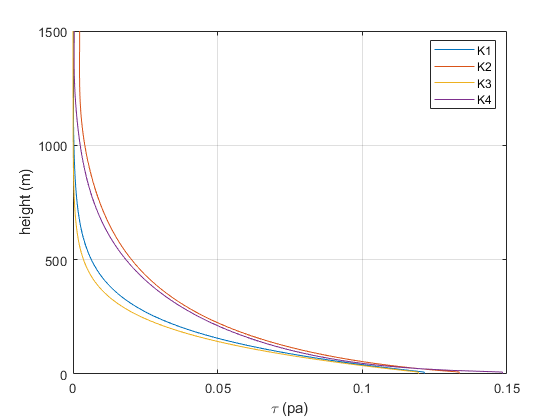


figure
for ii=1:Nk
    hold on; box on;
    plot(tau(ii,:),z)
    xlabel('\tau (pa)')
    ylabel('height (m)')
    set(gcf,'color','w')
end
legend('K1','K2','K3','K4','location','best')
grid on

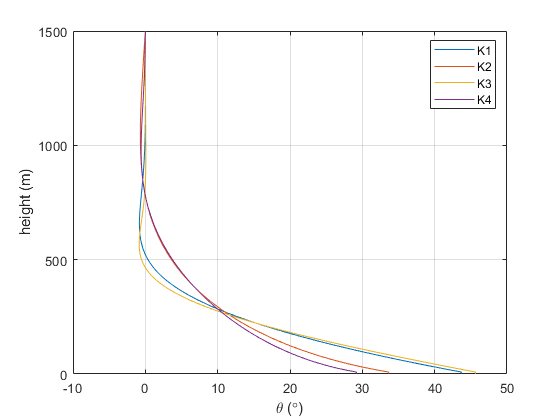


figure
for ii=1:Nk
    hold on; box on;
    plot(Theta(ii,:),z)
    xlabel('\theta ({\circ})')
    ylabel('height (m)')
    set(gcf,'color','w')
end
legend('K1','K2','K3','K4','location','best')
grid on

## With the Matlab function bcp4v

opts = bvpset('RelTol',0.1,'AbsTol',0.1,'Stats','on');
Omega = 7.29e-5;
f = 2*Omega*sind(abs(latitude));

% z = linspace(1,h,Nz); % height vector
Theta = nan(Nk,Nz);

figure
for ii=1:Nk
    
    [sol4c] = solveEkman_bcp4v(f,K(ii,:),Ug,z,opts,'Kp',Kp(ii,:));
    
    myZ = sol4c.x;
    myU = sol4c.y(1,:);

    Theta(ii,:) = 180/pi.*atan2(sol4c.y(2,:),sol4c.y(1,:));
    
    plot(myU,myZ)
    hold on; box on;
    xlabel('u (m s^{-1})')
    ylabel('height (m)')
    set(gcf,'color','w')
end

The solution was obtained on a mesh of 200 points.
The maximum residual is  3.085e-07. 
There were 1997 calls to the ODE function. 
There were 16 calls to the BC function. 


The solution was obtained on a mesh of 200 points.
The maximum residual is  5.479e-05. 
There were 2396 calls to the ODE function. 
There were 17 calls to the BC function. 


The solution was obtained on a mesh of 200 points.
The maximum residual is  1.995e-07. 
There were 1997 calls to the ODE function. 
There were 16 calls to the BC function. 


The solution was obtained on a mesh of 200 points.
The maximum residual is  8.199e-04. 
There were 2396 calls to the ODE function. 
There were 17 calls to the BC function. 


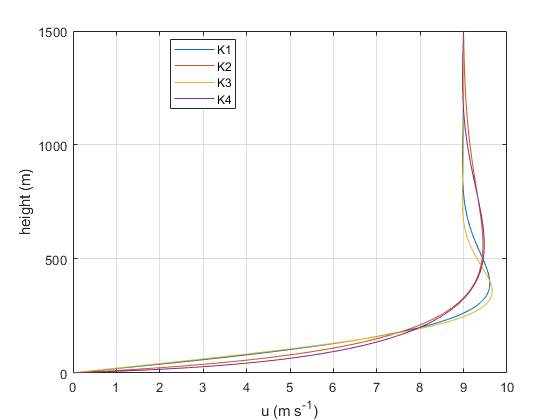

legend('K1','K2','K3','K4','location','best')
grid on

Theta(:,1) = Theta(:,2); % The bottom value is assumed equal to the second lowest one

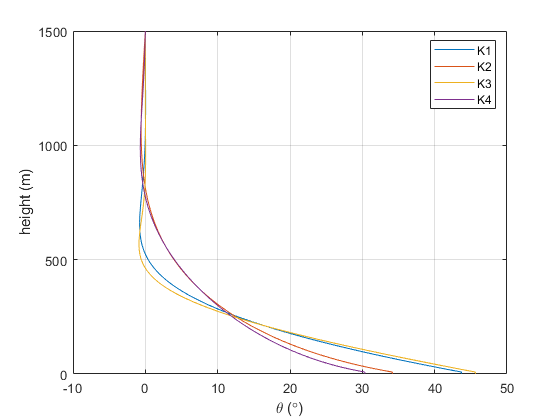

figure
for ii=1:Nk
    hold on; box on;
    plot(Theta(ii,:),z)
    xlabel('\theta ({\circ})')
    ylabel('height (m)')
    set(gcf,'color','w')
end
legend('K1','K2','K3','K4','location','best')
grid on